# Example 11.1: Using the Sobel edge detector.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

Of the first three detectors listed in Table 11.1, the Sobel detector is used more frequently so we work with it in this example. 

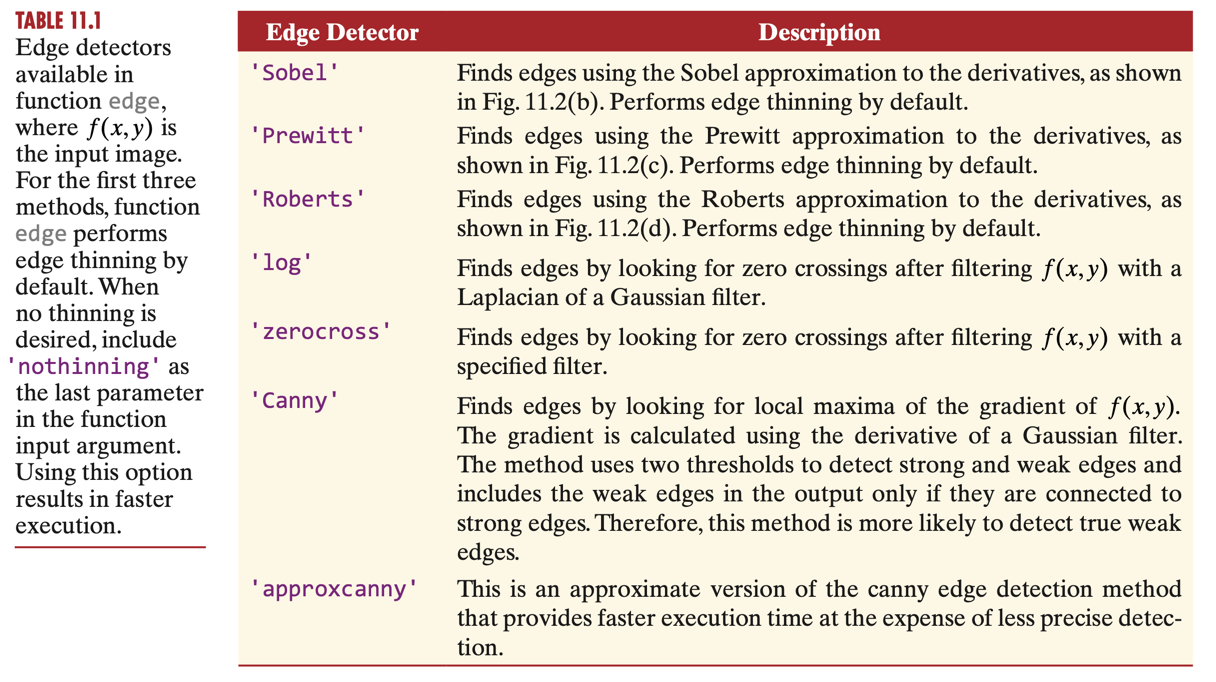

You will experiment with the other detectors in Projects 11.2 and 11.3. 

We begin by attempting to detect the principal vertical edges in the building shown in Fig. 11.4(a): 					

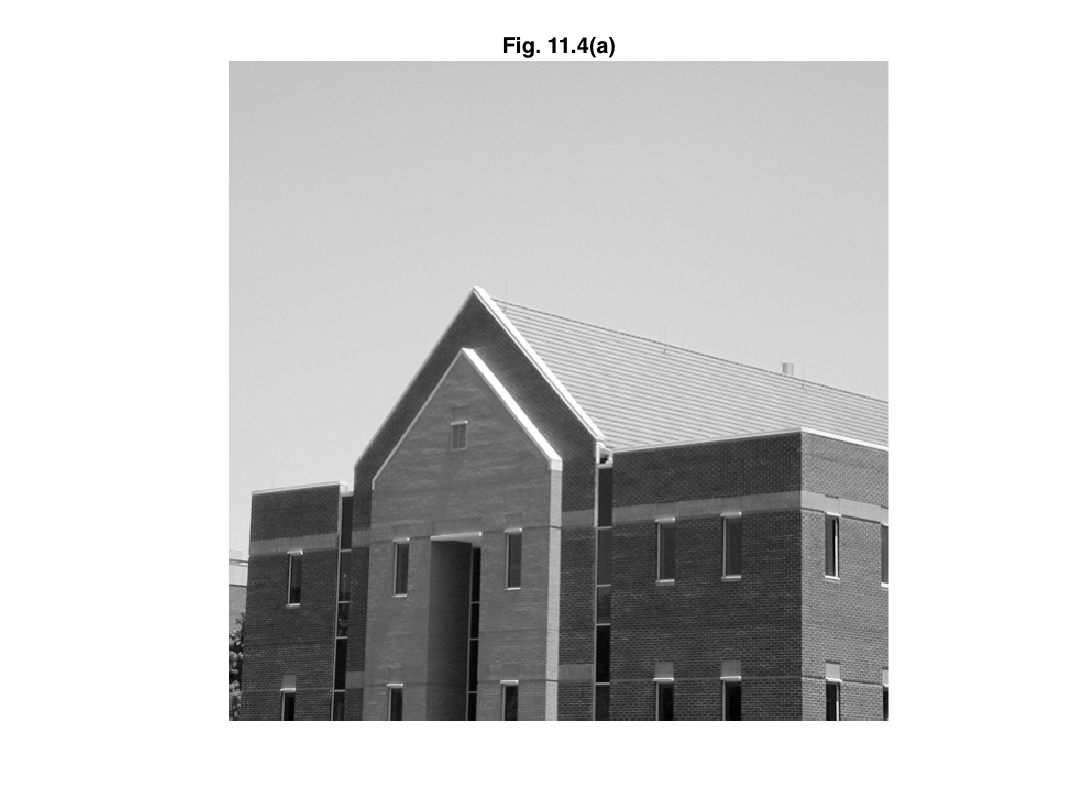

f = tofloat(imread('building.tif'));
figure, imshow(f), title('Fig. 11.4(a)')

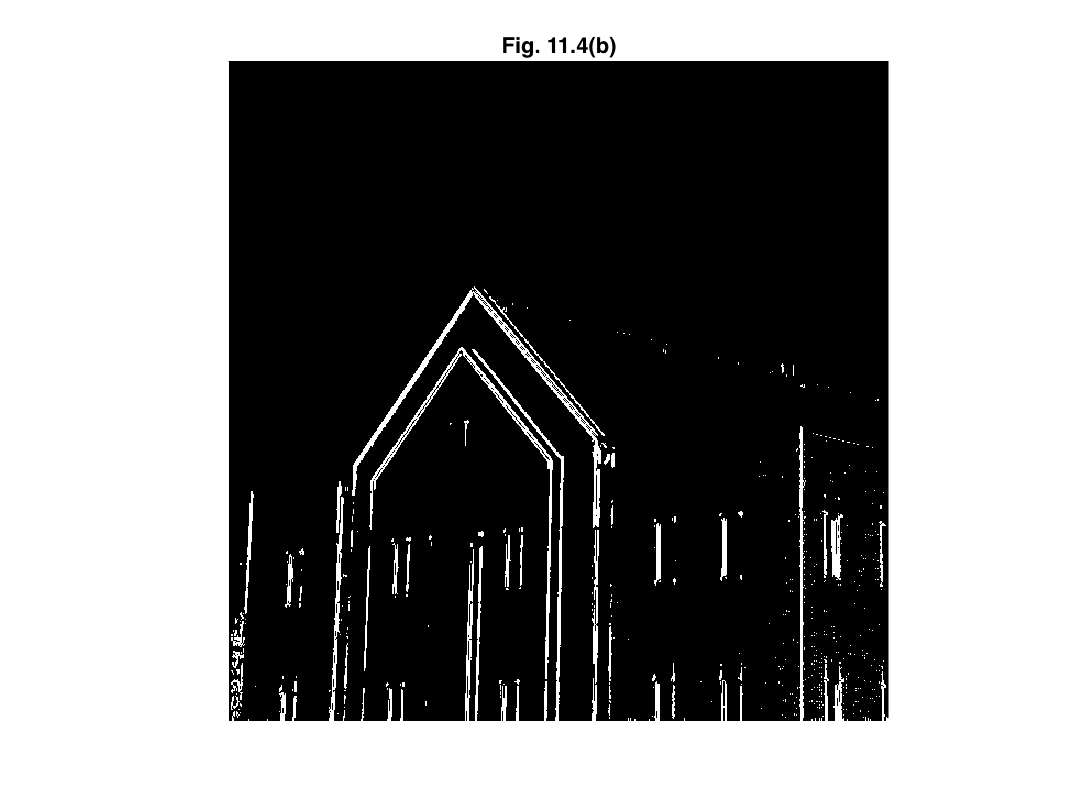


% As a starting point, let edge find the threshold.
[gv1,t1] = edge(f,'sobel','vertical','nothinning');
figure, imshow(gv1), title('Fig. 11.4(b)')

As Fig. 11.4(b) shows, the resulting edges are predominantly vertical (the inclined edges have vertical and horizontal components so they are detected as well). We can partially clean up the weaker edges by specifying a higher threshold value. We use `T = t1` as a starting point: 

t1

t1 = 0.0516

We had to increase the threshold to 0.10 to get a result in which the strong vertical edges are predominant. We obtained Fig. 11.4(c) using the following commands: 

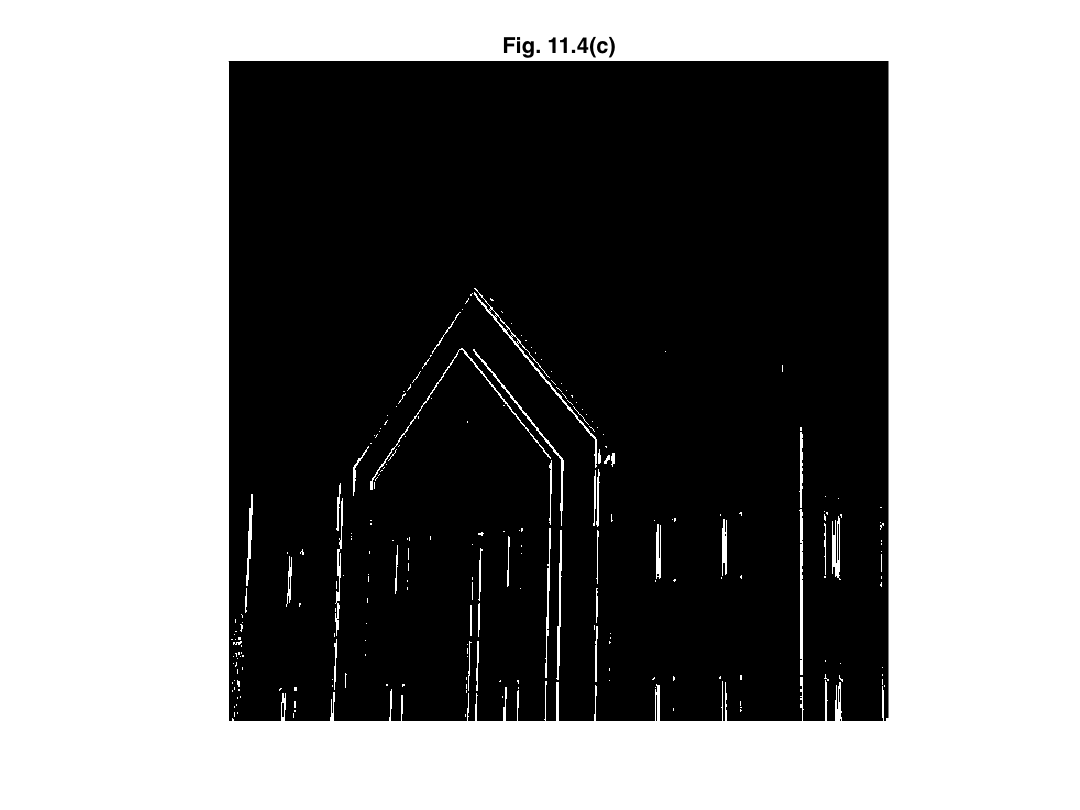

gv2 = edge(f,'sobel',0.10,'vertical','nothinning');
figure, imshow(gv2), title('Fig. 11.4(c)')

Using the same value of `T` in the commands

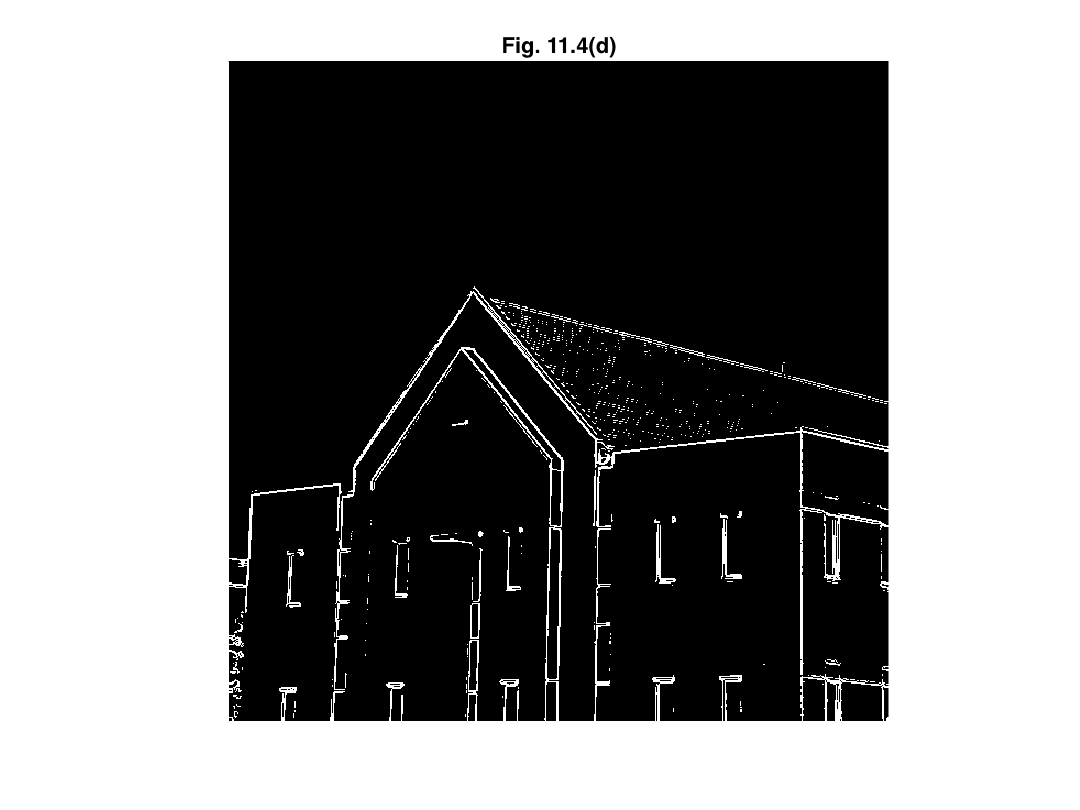

gboth = edge(f,'sobel',0.10,'nothinning'); 
figure, imshow(gboth), title('Fig. 11.4(d)')

resulted in Fig. 11.4(d), which shows predominantly vertical and horizontal edges.

Function `edge` does not compute Sobel edges at $\pm 45^\circ$. To compute such edges we use the kernels in Fig. 11.3 and function `imfilter`. For example, we generated Fig. 11.4(e) using the commands 

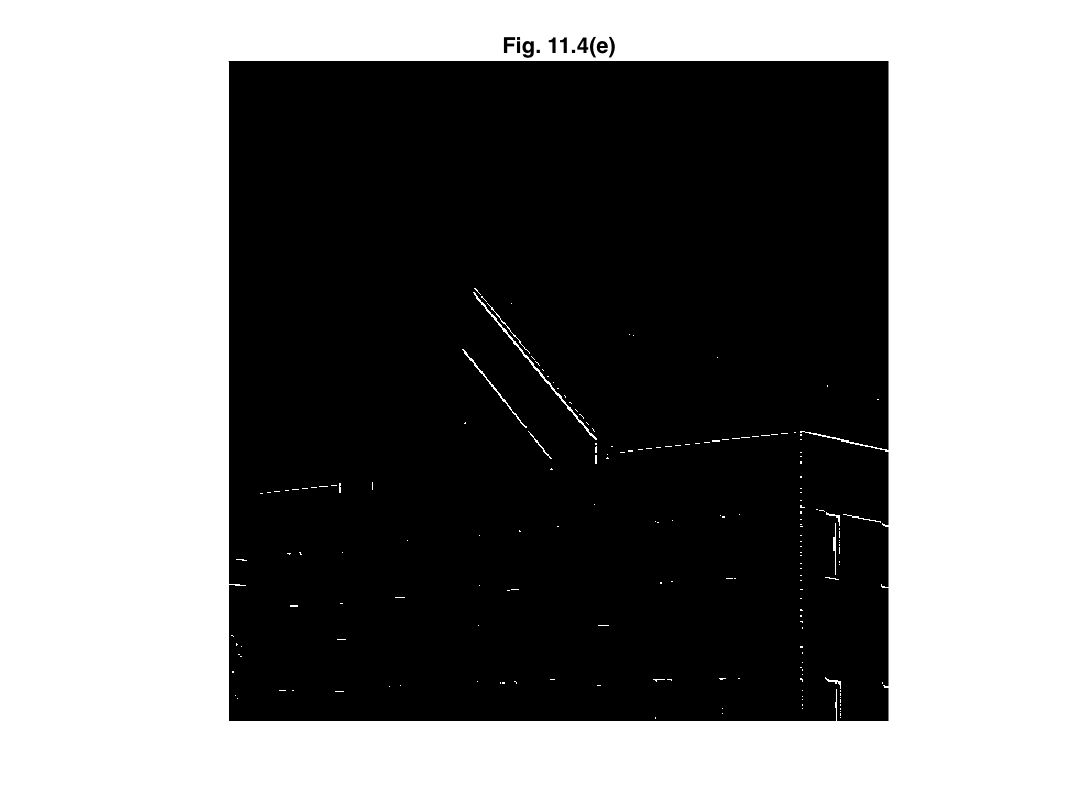

wpos45 = [0 1 2; -1 0 1; -2 -1 0]; % From Fig. 11.3(a).
gpos45 = imfilter(f,wpos45,'replicate');
gpos45 = gpos45 >= 0.4*max(abs(gpos45(:)));
figure, imshow(gpos45), title('Fig. 11.4(e)')

The third step thresholded the image after it was filtered. To simplify threshold selection, we used a fraction of the maximum absolute value in the filtered image. In this case using 40% of the maximum value extracted the edges oriented predominantly at $\pm 45^\circ$. A similar set of commands using the same threshold and the kernel in Fig. 11.3(b) resulted in Fig. 11.4(f), whose principal edge is in the $-45^\circ$ direction. 

**Fig. 11.4(f)**